Load the image.

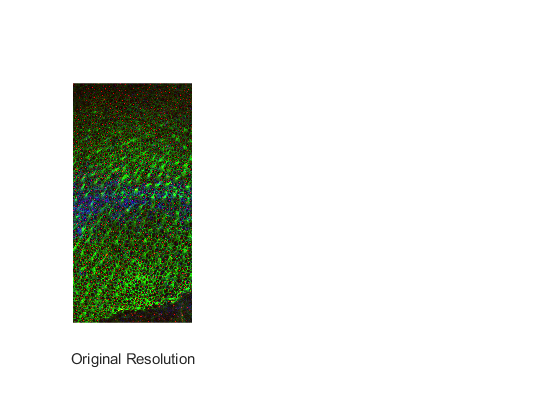

RAW = imread('../Data/Example Images/Raw/C57_WT_Utricle_1_RawRect-01.png');

figure
subplot(1,3,1)
imshow(RAW)
xlabel('Original Resolution')

Note that the raw image is very large and as a result all operations will take a long time to complete. Fortunately, cells are large with respect to the pixels in the image so we don't need all this information to correctly identify cells. To address the issue we can downsample the image.

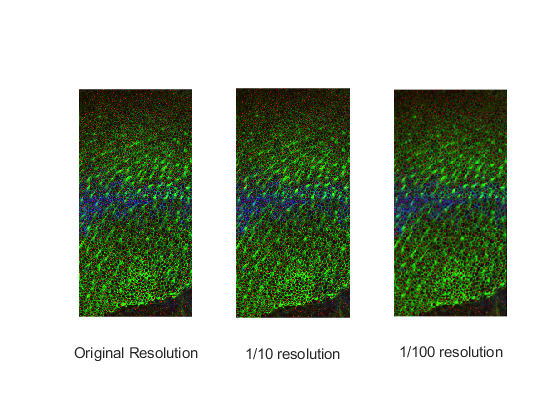

dRAW10 = imresize(RAW,0.1);
subplot(1,3,2)
imshow(dRAW10)
xlabel('1/10 resolution')

dRAW100 = imresize(RAW,0.01);
subplot(1,3,3)
imshow(dRAW100)
xlabel('1/100 resolution');

Note how at 1/10 resolution the boundaries between cells are still distinguishable and roughly the same size as in the original resolution image, whereas in the the 1/100 resolution image the same is not true. Specifying an appropriate and consistent downsampling rate will be important moving forward. 

For now we will use a downsampling scale of 1/20. Enough to speed up process.

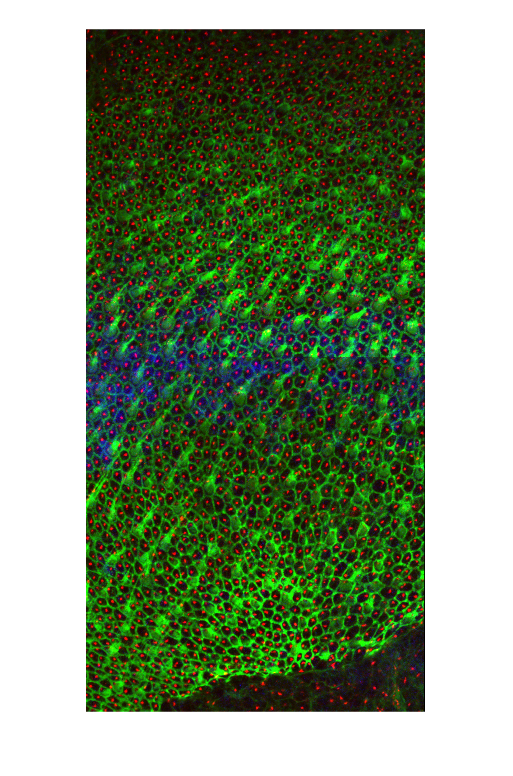


dRAW = imresize(RAW,0.05);

figure
imshow(dRAW)

Next we want to isolate each of the channels of the image.

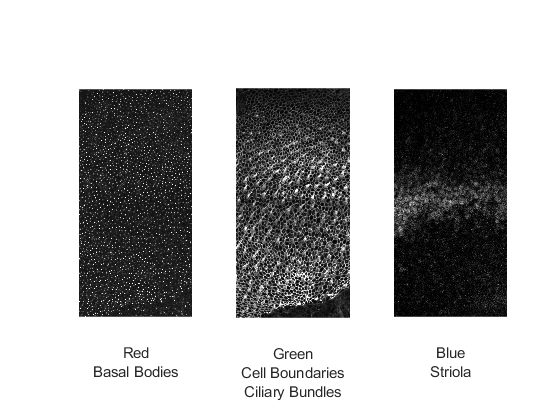

imR = dRAW(:,:,1);
imG = dRAW(:,:,2);
imB = dRAW(:,:,3);

figure
subplot(1,3,1)
imshow(imR)
xlabel({'Red','Basal Bodies'})

subplot(1,3,2)
imshow(imG)
xlabel({'Green','Cell Boundaries','Ciliary Bundles'})

subplot(1,3,3)
imshow(imB)
xlabel({'Blue','Striola'})

We will use the Green channel to identify cells as it labels the cell boundaries and cells are clearly visible as voids in the image. 

Notice how the flourescence in the green channel is not even throughout the image. It's dimmer near the top. This is called uneven illumination and can be corrected for. The trick is to first blur the original image to get an approximation of the uneven illumination, then divide the original image by the blurred image. Finally, the divided image is contrasted to show it's full dynamic range. 


diskRad = 100;
imBlur = imgaussfilt(imG,100);
imGEven = double(imG)./double(imBlur);
maxPix = max(imGEven(:));


Contrast the divided image. saturating the bottom 1% and the top 1% of all pixels values.

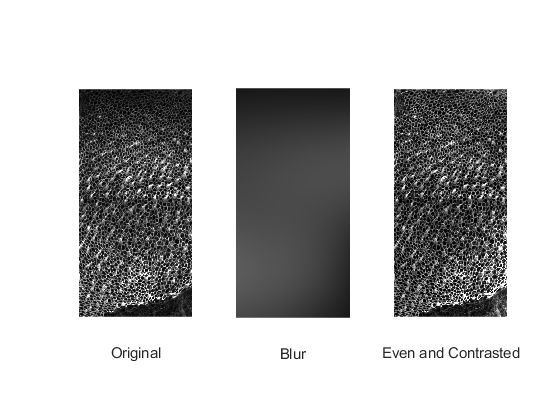

lowThresh = prctile(imGEven(:),1);
highThresh = prctile(imGEven(:),99);

imGAdj = uint8(255*(imGEven-lowThresh)/(highThresh-lowThresh));


figure
subplot(1,3,1)
imshow(imG)
xlabel('Original')

subplot(1,3,2)
imshow(imBlur)
xlabel('Blur')

subplot(1,3,3)
imshow(imGAdj)
xlabel('Even and Contrasted')

Note how the original shapes in the image have not changed but the illumination is now even. 

The next thing we have to worry about are the ciliary clusters. These mask the boundary between cells and cover up hair cells. Fortunately, they are all roughly the same size. To get rid of them we can use a tophat transformation. After that, we can automatically threshold the image to convert it to binary and invert it so that boundaries are black and cells are white. 


imTH = imtophat(imGAdj,strel('disk',4));

imBW = ~imbinarize(imTH,'adaptive');


figure
imshow(imGAdj)

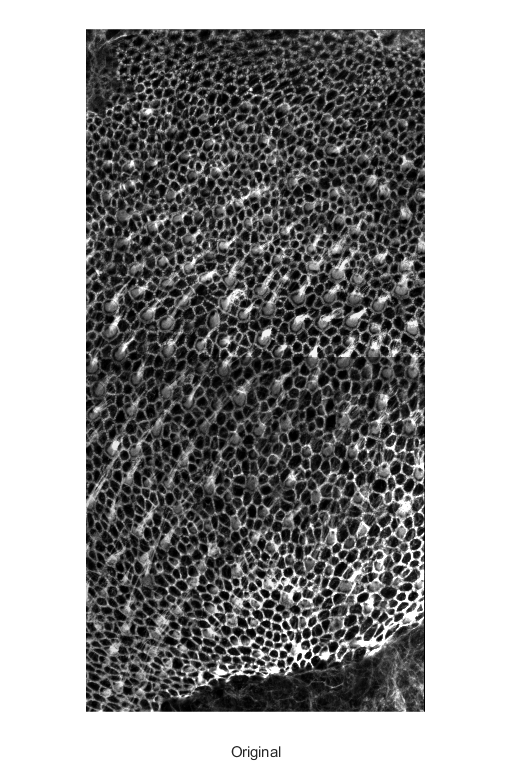

xlabel('Original')


figure
imshow(imTH)

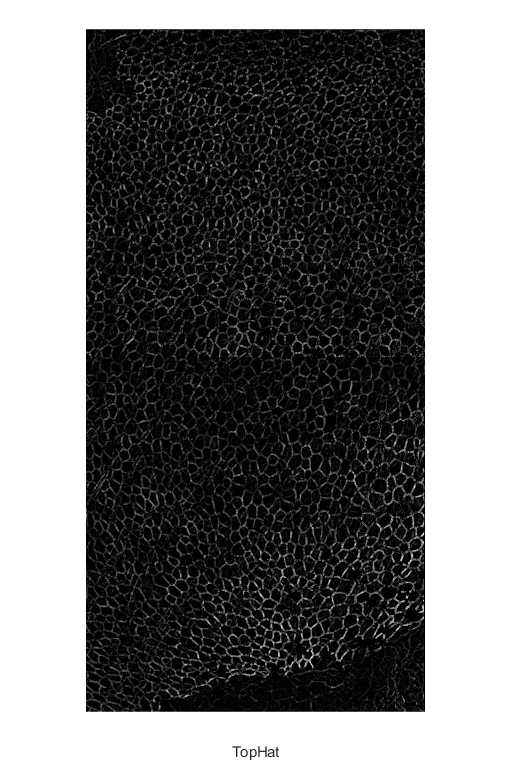

xlabel('TopHat')


figure
imshow(imBW)

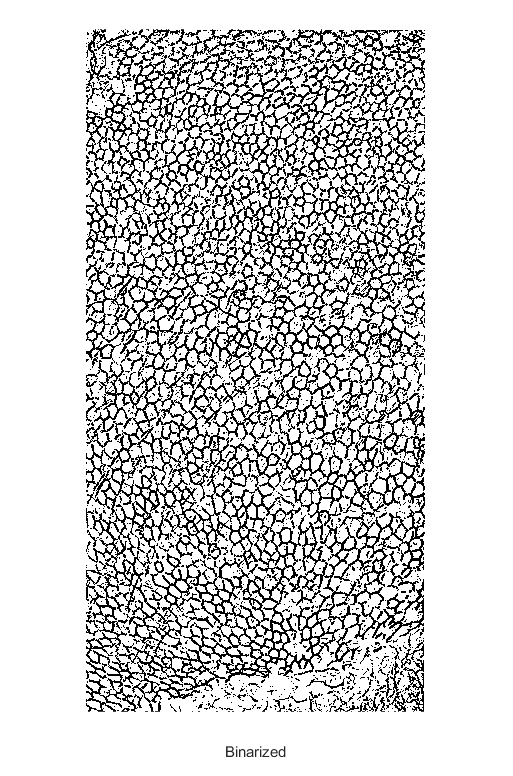

xlabel('Binarized')

Next, we have to refine the binary image. Using a binary open we can solidify the boundaries between cells. Next, we can remove noise using an area-based close.

 
imClose = ~bwareaopen(~imBW,30);
imshow(imClose)

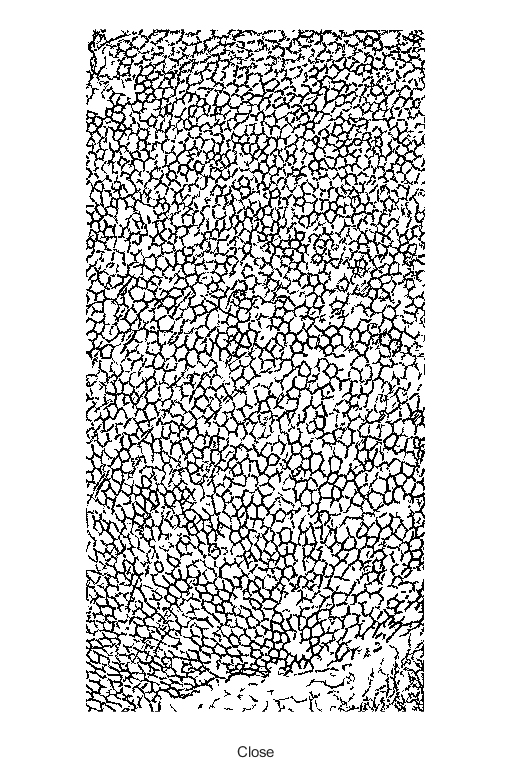

xlabel('Close')


imOpen = imopen(imClose,strel('disk',2));
imOpen = bwareaopen(imOpen,50);
imshow(imOpen)

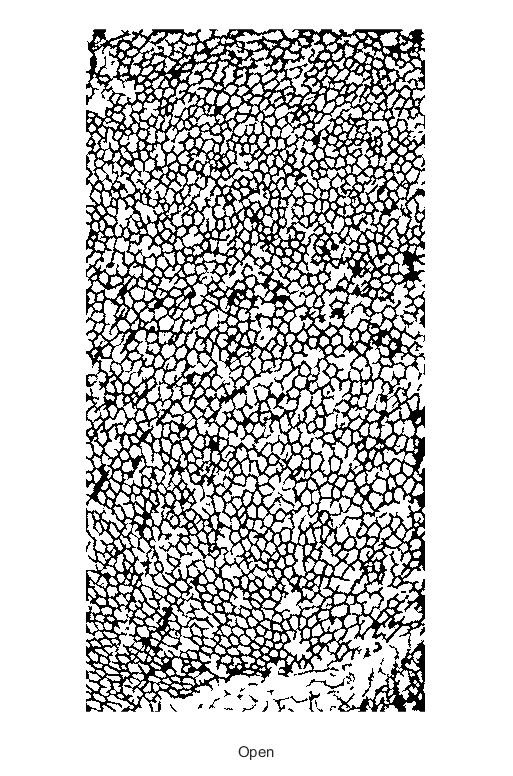

xlabel('Open')

The selection is close, but still isn't perfect. The last thing we need to do is make sure all the boundaries are connected. A watershed segmentation can do that but we have to massage this image just a bit before we can use the watershed transformation to separate the cells. 

The trick with using the watershed transformation is ot change your image into another image whose catchment basins are the objects you want to identify. 

The first step to do this is to compute the distance transform.

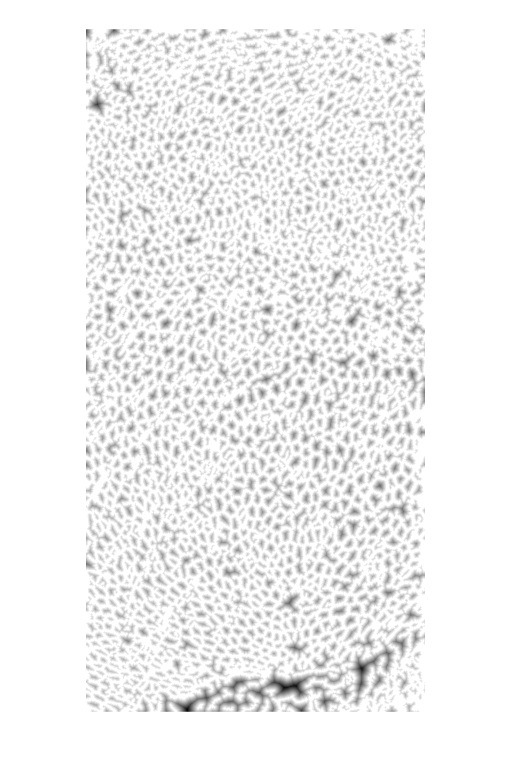

D = -bwdist(~imOpen);
imshow(D,[])

Next compute the watershed transform of D.

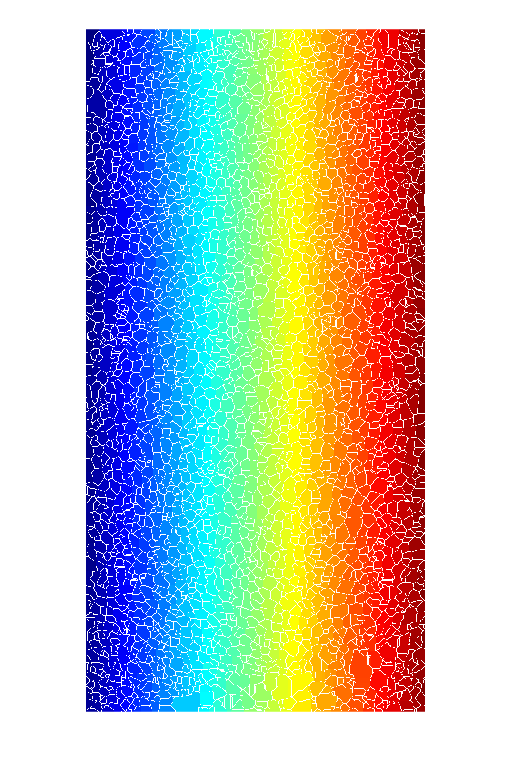

Ld = watershed(D);
imshow(label2rgb(Ld))

The watershed ridge lines are shown in white. Lets use them to segment the binary image by setting the corresponding pixels to black.

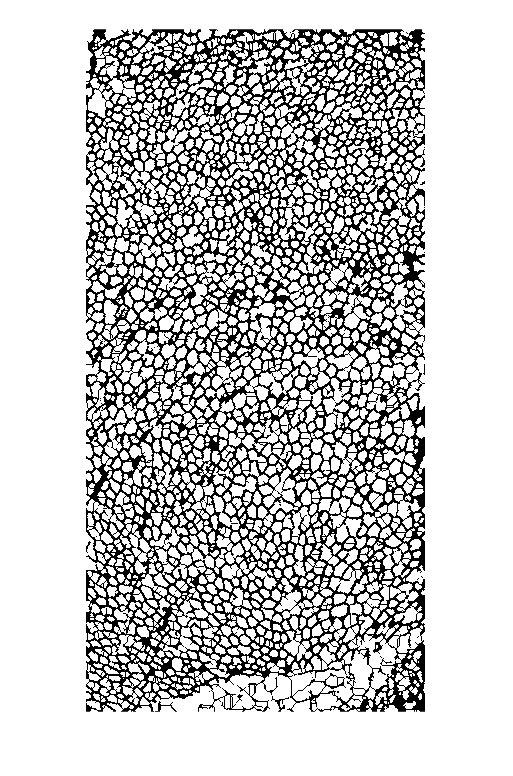

bw2 = imOpen;
bw2(Ld==0) = 0;
imshow(bw2)

The raw watershed transform tends to oversegment an image. We can tweak our image further to reduce this.Using imextendmin should produce spots roughly at the center of each cell.

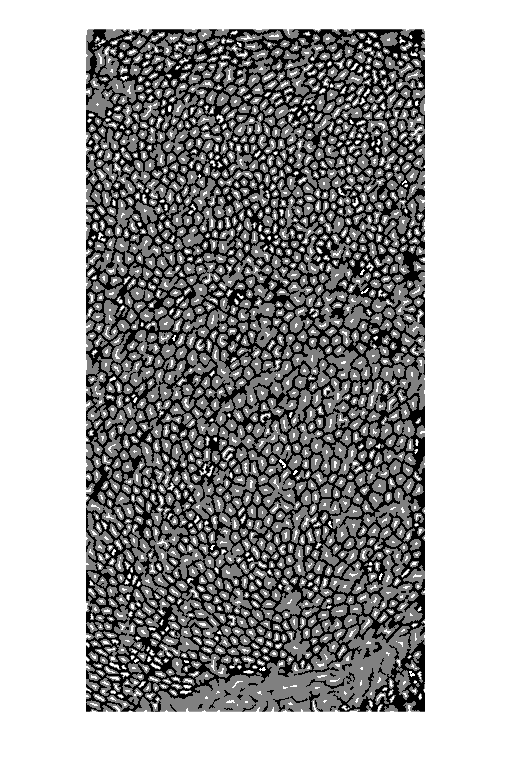

mask = imextendedmin(D,2);
imshowpair(imOpen,mask,'blend')

Modify the distance transform so it only has minima at the locations we identified in the previous image then repeat the watershed steps.

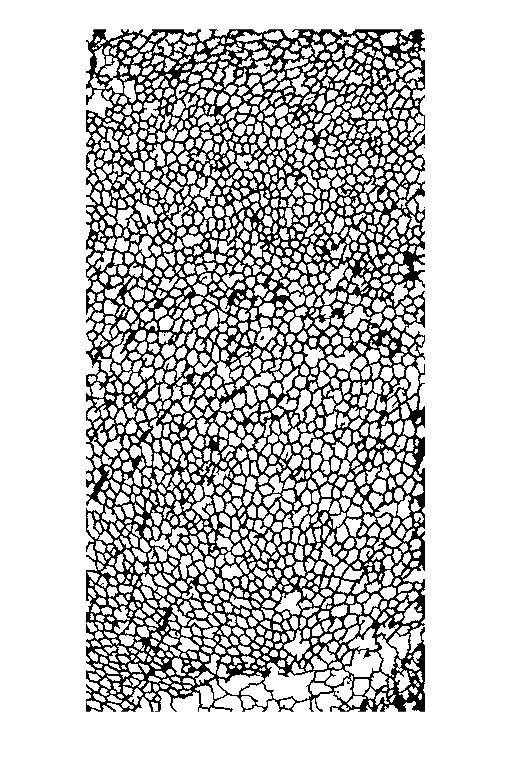

D2 = imimposemin(D,mask);
Ld2 = watershed(D2);
Ld2 = imerode(Ld2,strel('disk',1)); % thicken the watershed lines a bit.
bw3 = imOpen;
bw3(Ld2 == 0) = 0;
imshow(bw3)

At this point, we want to eliminate components based on their morphology.For example, the very large regions at the bottom of the image are not cells. We can omit these based on their perimeter.  

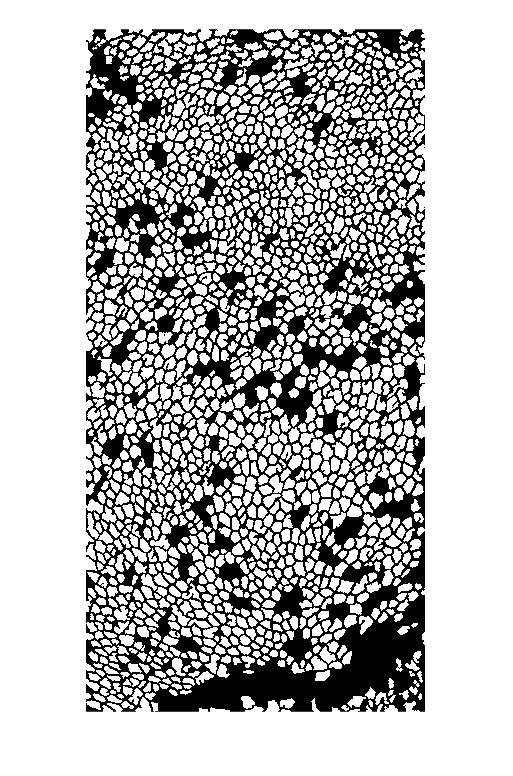

AreaThresh = [75,600];
bw4 = regionthresh(bw3,'Area',AreaThresh);
imshow(bw4)

Next we just have to assign a label to each of the connecte components in the 2D binary image. 

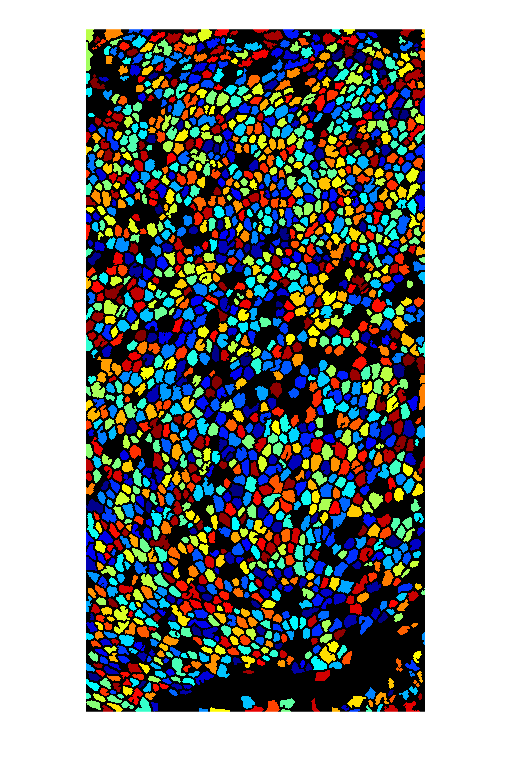

[L,nComps] = bwlabel(bw4);
LRGB = label2rgb(L,'jet','k','shuffle');
imshow(LRGB)

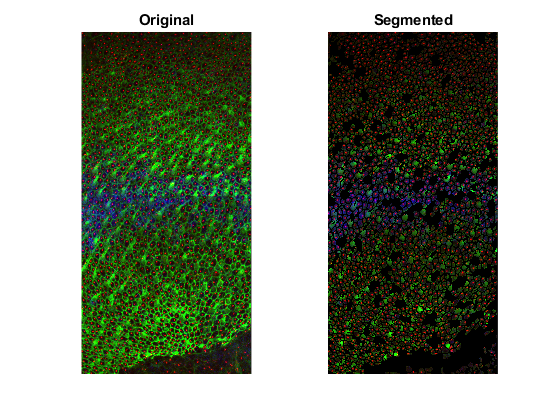

figure
subplot(1,2,1)
imshow(dRAW)
title('Original')

subplot(1,2,2)
imshow(uint8(double(dRAW).*double(bw4)))
title('Segmented')

Yay, At this point the cells have been segmented and we can now analyze their additional properties. There are still a few false positives (at the bottom of the image) and a few false negatives(black spots spread throughout) the image but overall we got the majority of the cells. We can further refine our selection when we analyze the cells. 

The last thing to do is separate all the components of the image, so they can be individually analyzed. 

figure
% CellsIm = cell(1,nComps);
% for k = 1:nComps
% % Isolate object
%     Blob = ismember(L,k);
%     [rows,cols] = find(Blob);
%     Blob = Blob(min(rows):max(rows), min(cols):max(cols));
%     BlobIm = dRAW(min(rows):max(rows), min(cols):max(cols),:);
%     BlobIm = uint8(double(Blob).*double(BlobIm));
%     CellsIm{k} = BlobIm;
% end
CellsIm = labelSeparate(dRAW,L);
figure
montage(CellsIm)

Error using images.internal.getImageFromFile (line 7)
The specified filename is not a string.

Error in montage>getImageFromFilenames (line 357)
    [I, map] = images.internal.getImageFromFile(fileNames{idx});

Error in 

title('Separated Cells')